## **EEG Data Spectrogram Analysis**

**Team Members**

- **Youssef Alaa  202100601**

- **Ahmed Samy 202100922**

- **Omar Samy    202101018**

### **Introduction**

#### **Objective**

This project focuses on analyzing EEG data to distinguish seizure (ictal) and non-seizure (seizure-free) brain activity using spectrogram representations. The tasks include preprocessing the data, computing spectrograms, and investigating the effects of overlapping, window sizes, and window types.

### **EEG Data Description**

- **Dataset**: CHB-MIT Scalp EEG Dataset.

- **Channels**: 29 (multi-channel recordings).

- **Sampling Rate**: 256 Hz.

- **Seizure Data**: Segments of ictal periods provided in `chb12_29_data.mat`.

- **Seizure-Free Data**: Entire duration provided in `chb12_32_data.mat`.

### Task 1: Preprocessing the EEG Data

#### **Objective**

To extract ictal and seizure-free segments from the EEG data based on given seizure timings.

#### **Code Explanation**

- **Load Data**: Load `.mat` files containing raw EEG data.

- **Extract Ictal Segments**: Use the provided seizure timings to extract seizure periods.

- **Save Processed Data**: Save both ictal and seizure-free data as separate `.mat` files.

#### **Mathematics**

The seizure segments are defined by:


$$\mathrm{Start}\mathrm{Index}=\mathrm{Start}\mathrm{Time}\times \mathrm{Sampling}\mathrm{Rate}+1$$



$$\mathrm{End}\mathrm{Index}=\mathrm{End}\mathrm{Time}\times \mathrm{Sampling}\mathrm{Rate}$$


#### Code

% Load the .mat files
ictal_data_raw = load('chb12_29_data.mat'); % Data with seizures
interictal_data_raw = load('chb12_32_data.mat'); % Data without seizures

% Access the 'data' variable from the loaded structures
ictal_data = ictal_data_raw.data;
seizure_free_data = interictal_data_raw.data; % Directly use seizure-free data

% Define sampling rate
sampling_rate = 256; % Hz (as specified in the assignment)

% Seizure times from chb12-summary.txt (in seconds)
seizure_times = [
    107, 146;
    554, 592;
    1163, 1199;
    1401, 1447;
    1884, 1921;
    3557, 3584
];

% Extract ictal (seizure) states
ictal_segments = {};
for i = 1:size(seizure_times, 1)
    start_idx = seizure_times(i, 1) * sampling_rate + 1; % Convert time to sample index
    end_idx = seizure_times(i, 2) * sampling_rate;
    ictal_segments{i} = ictal_data(start_idx:end_idx, :); % Extract seizure segment
end

% Combine all ictal segments into one matrix
ictal_combined = cell2mat(ictal_segments'); % Concatenate along the time dimension

% Save processed data
save('ictal_data.mat', 'ictal_combined'); % Save seizures-only data
save('seizure_free_data.mat', 'seizure_free_data'); % Directly save seizure-free data from chb12_32

disp('Seizure-only and seizure-free records have been saved.');

Seizure-only and seizure-free records have been saved.


### Task 2: Channel Selection and Averaging

#### **Objective**

Allow the user to select channels and compute the average signal for selected channels.

#### **Code Explanation**

- **User Selection**: Use a pop-up dialog box to select channels.

- **Averaging**: Compute the mean signal across selected channels for both ictal and seizure-free data.

#### **Mathematics**

For each time step:


$$\mathrm{Averaged}\mathrm{Signal}=\frac{\sum_{i=1}^N {\mathrm{Channel}}_i }{N}$$


#### Code

% Load processed data
ictal_data = load('ictal_data.mat');
seizure_free_data = load('seizure_free_data.mat');

ictal_data = ictal_data.ictal_combined; % Access the ictal data matrix
seizure_free_data = seizure_free_data.seizure_free_data; % Access the seizure-free data matrix

% Define the available channels
num_channels = size(ictal_data, 2); % Total number of channels (29)
channel_labels = strcat("Channel ", string(1:num_channels)); % Create labels for channels

% User selection of channels
selected_channels = listdlg('PromptString', 'Select channels to average:', ...
                             'SelectionMode', 'multiple', ...
                             'ListString', channel_labels);

if isempty(selected_channels)
    error('No channels were selected. Please run the script again and select at least one channel.');
end

% Average across selected channels
ictal_averaged = mean(ictal_data(:, selected_channels), 2); % Average along the channel dimension
seizure_free_averaged = mean(seizure_free_data(:, selected_channels), 2);

% Save the averaged data
save('ictal_averaged.mat', 'ictal_averaged');
save('seizure_free_averaged.mat', 'seizure_free_averaged');

disp('Averaged ictal and seizure-free data have been saved.');

Averaged ictal and seizure-free data have been saved.


**Note:** The channels selected are **1, 2, 3, 6.**

### Task 3: Spectrogram Computation

#### **Objective**

Generate spectrograms for ictal and seizure-free data using STFT.

#### **Code Explanation**

- **Short-Time Fourier Transform (STFT)**: Divide the signal into windows, apply FFT to each window, and generate time-frequency representations.

- **Hamming Window**: Default window applied to reduce edge effects.

#### **Mathematics**

STFT is defined as:


$$\mathrm{STFT}\left\lbrace x\left(t\right)\right\rbrace =X\left(t,f\right)=\int_{-\infty }^{\infty } x\left(\tau \right)\omega \left(t-\tau \right)e^{-\mathrm{j2}\pi f\tau } d\tau$$


#### Code

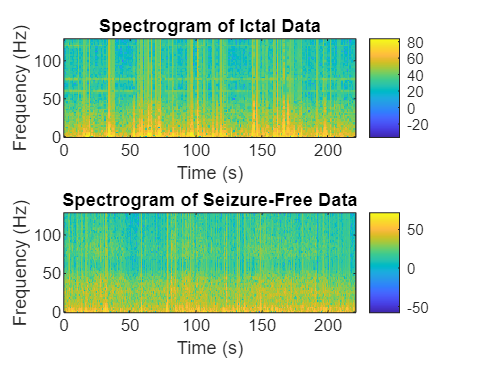

% Load the preprocessed averaged data
ictal_averaged_data = load('ictal_averaged.mat').ictal_averaged;
seizure_free_averaged_data = load('seizure_free_averaged.mat').seizure_free_averaged;

% Define parameters
Fs = 256; % Sampling rate in Hz
n_seconds = input('Enter the time resolution in seconds (e.g., 2): ');
n_freqs = input('Enter the frequency resolution in samples (e.g., 128): ');

% Calculate the number of samples per time window
window_size = n_seconds * Fs;

% Define overlap (optional, set to 50% overlap)
overlap = round(0.5 * window_size);

% Create Hamming window
window = hamming(window_size);



% Compute spectrograms for ictal and seizure-free data
ictal_spectrogram = compute_spectrogram(ictal_averaged_data, window, overlap, n_freqs, window_size, Fs);
seizure_free_spectrogram = compute_spectrogram(seizure_free_averaged_data, window, overlap, n_freqs, window_size, Fs);

% Time and frequency axes
time_axis = (0:(size(ictal_spectrogram, 2) - 1)) * (window_size - overlap) / Fs;
freq_axis = (0:(n_freqs / 2)) * Fs / n_freqs;

% Plot spectrograms
figure;
subplot(2, 1, 1);
imagesc(time_axis, freq_axis, ictal_spectrogram);
axis xy;
xlabel('Time (s)');
ylabel('Frequency (Hz)');
title('Spectrogram of Ictal Data');
colorbar;

subplot(2, 1, 2);
imagesc(time_axis, freq_axis, seizure_free_spectrogram);
axis xy;
xlabel('Time (s)');
ylabel('Frequency (Hz)');
title('Spectrogram of Seizure-Free Data');
colorbar;

**Note:** The function **"compute_spectrogram"** is defined in a separate          file.

#### Output 

***"Spectrogram Output for Ictal and Seizure-Free Data"***

**Input Parameters**

- **Time Resolution**: 2 seconds

- **Frequency Resolution**: 128 samples

**Explanation**

The figure displays the spectrograms for both ictal (seizure) and seizure-free data, showing the frequency content of the EEG signals over time:

**Spectrogram of Ictal Data (Top Plot)**:

- **Time (X-axis)**: Represents the duration of the seizure event in seconds.

- **Frequency (Y-axis)**: Displays the frequency components of the signal in Hz.

- **Color Intensity**: Indicates the magnitude of each frequency component in dB.

- Brighter (yellow) areas signify higher magnitude (stronger frequency signals).

- Darker (blue) areas represent weaker frequency signals.

- **Observation**:

- The ictal data shows periodic bursts of high-intensity frequencies, evident in the vertical yellow bands. This indicates distinctive seizure activity, where certain frequencies dominate during seizures.

**Spectrogram of Seizure-Free Data (Bottom Plot)**:

- **Time (X-axis)**: Represents the duration of the seizure-free recording in seconds.

- **Frequency (Y-axis)**: Displays the frequency components of the signal in Hz.

- **Color Intensity**: Similar to the ictal data, the brighter areas indicate stronger frequency signals.

- **Observation**:

- The seizure-free data lacks the periodic bursts seen in the ictal data. The frequency content appears more uniform and less intense, reflecting typical brain activity without seizures.

**Significance**

- The comparison highlights the distinct frequency characteristics of seizure events compared to normal brain activity.

- This visualization helps in understanding how brainwave frequencies evolve during seizures and can be used for diagnostic or analytical purposes.

### Task 4: Investigating Overlapping Ratios

#### **Objective**

Analyze the effect of different overlapping ratios on the spectrogram.

#### **Code Explanation**

- **Overlap Ratios**: Tested 0%, 25%, 50%, and 75%.

- **Effect**: High overlap creates smoother spectrograms but increases computational cost.

#### Code

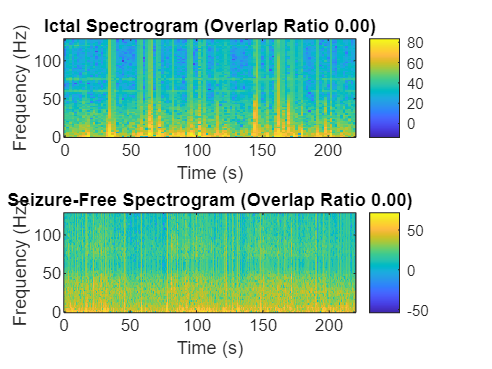

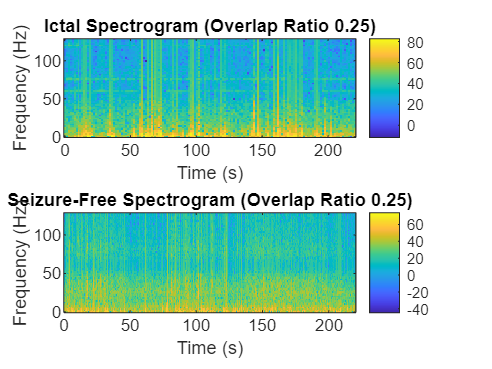

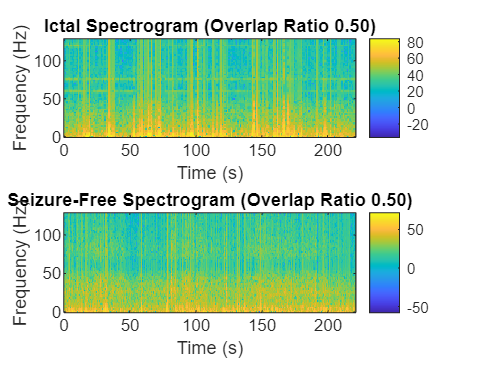

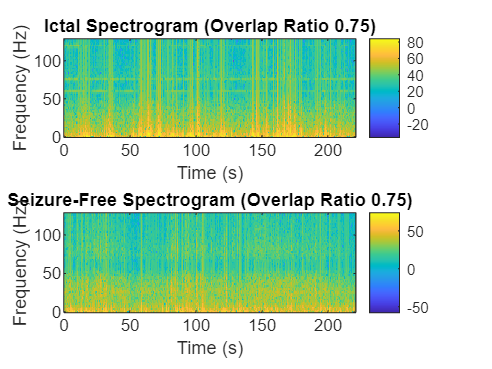

% Load the preprocessed averaged data
ictal_averaged_data = load('ictal_averaged.mat').ictal_averaged;
seizure_free_averaged_data = load('seizure_free_averaged.mat').seizure_free_averaged;

% Sampling rate
Fs = 256; % Hz

% Part 1: Investigate Overlapping Ratios
overlap_ratios = [0, 0.25, 0.5, 0.75]; % Test these ratios
n_seconds = 2; % Fixed time resolution (can be modified)
window_size = n_seconds * Fs; % Window size in samples
n_freqs = 128; % FFT size

% Loop over overlap ratios
for ratio = overlap_ratios
    overlap = round(ratio * window_size); % Compute overlap in samples
    window = hamming(window_size); % Hamming window

    % Compute spectrograms
    ictal_spectrogram = compute_spectrogram(ictal_averaged_data, window, overlap, n_freqs, window_size, Fs);
    seizure_free_spectrogram = compute_spectrogram(seizure_free_averaged_data, window, overlap, n_freqs, window_size, Fs);

    % Time and frequency axes
    time_axis = (0:(size(ictal_spectrogram, 2) - 1)) * (window_size - overlap) / Fs;
    freq_axis = (0:(n_freqs / 2)) * Fs / n_freqs;

    % Plot results
    figure('Name', sprintf('Overlap Ratio: %.2f', ratio));
    subplot(2, 1, 1);
    imagesc(time_axis, freq_axis, ictal_spectrogram);
    axis xy;
    xlabel('Time (s)');
    ylabel('Frequency (Hz)');
    title(sprintf('Ictal Spectrogram (Overlap Ratio %.2f)', ratio));
    colorbar;

    subplot(2, 1, 2);
    imagesc(time_axis, freq_axis, seizure_free_spectrogram);
    axis xy;
    xlabel('Time (s)');
    ylabel('Frequency (Hz)');
    title(sprintf('Seizure-Free Spectrogram (Overlap Ratio %.2f)', ratio));
    colorbar;
end

#### Output

**1. Overlap Ratio: 0.00**

**Ictal Spectrogram (Top)**:

- The time axis shows distinct, separate blocks of data due to the lack of overlap between windows.

- High-intensity frequencies (bright yellow bands) indicate seizure activity, but the lack of overlap causes discontinuities.

**Seizure-Free Spectrogram (Bottom)**:

- The frequency content appears uniform and consistent, representing normal brain activity.

- Non-overlapping segments result in a less smooth spectrogram.

**2. Overlap Ratio: 0.25**

**Ictal Spectrogram (Top)**:

- The overlapping of 25% smooths the transitions between adjacent time windows.

- Seizure-related frequency bursts (vertical yellow bands) remain distinct but slightly smoother.

**Seizure-Free Spectrogram (Bottom)**:

- The transitions between time windows are less abrupt compared to 0% overlap.

- Frequency patterns of normal activity are better visualized.

**3. Overlap Ratio: 0.50**

**Ictal Spectrogram (Top)**:

- 50% overlap significantly reduces discontinuities in the spectrogram.

- The periodic bursts of high-frequency seizure activity are now more continuous and better defined.

**Seizure-Free Spectrogram (Bottom)**:

- Normal brain activity is visualized with improved smoothness, showing gradual transitions between time frames.

**4. Overlap Ratio: 0.75**

**Ictal Spectrogram (Top)**:

- The high overlap (75%) provides the smoothest transitions, creating a seamless spectrogram.

- High-frequency seizure-related bands (yellow regions) are well-preserved and detailed.

**Seizure-Free Spectrogram (Bottom)**:

- The smoothest representation of normal activity, with no abrupt transitions in the spectrogram.

### Task 5: Investigating Window Sizes

#### **Objective**

Analyze the effect of varying window sizes on time and frequency resolution.

#### **Code Explanation**

- **Window Sizes**: Tested 1 second, 2 seconds, and 4 seconds.

- **Effect**: Smaller windows provide better time resolution, while larger windows improve frequency resolution.

#### Code

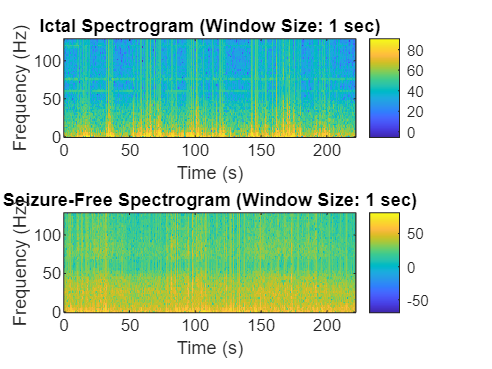

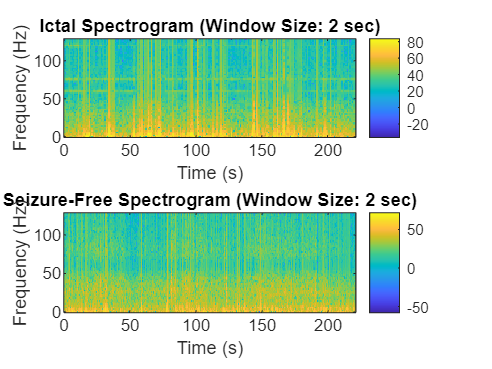

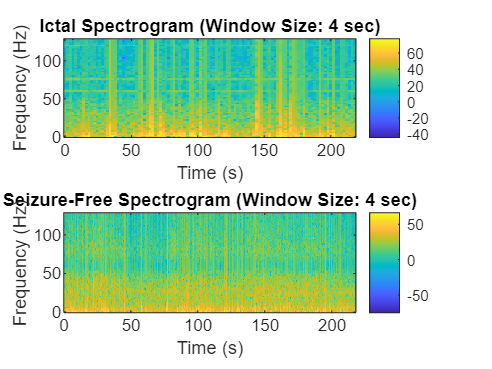

% Part 2: Investigate Window Sizes
window_sizes = [1, 2, 4]; % Test window sizes in seconds

% Loop over window sizes
for win_sec = window_sizes
    window_size = win_sec * Fs; % Convert to samples
    overlap = round(0.5 * window_size); % Fixed 50% overlap
    window = hamming(window_size); % Hamming window

    % Compute spectrograms
    ictal_spectrogram = compute_spectrogram(ictal_averaged_data, window, overlap, n_freqs, window_size, Fs);
    seizure_free_spectrogram = compute_spectrogram(seizure_free_averaged_data, window, overlap, n_freqs, window_size, Fs);

    % Time and frequency axes
    time_axis = (0:(size(ictal_spectrogram, 2) - 1)) * (window_size - overlap) / Fs;
    freq_axis = (0:(n_freqs / 2)) * Fs / n_freqs;

    % Plot results
    figure('Name', sprintf('Window Size: %d seconds', win_sec));
    subplot(2, 1, 1);
    imagesc(time_axis, freq_axis, ictal_spectrogram);
    axis xy;
    xlabel('Time (s)');
    ylabel('Frequency (Hz)');
    title(sprintf('Ictal Spectrogram (Window Size: %d sec)', win_sec));
    colorbar;

    subplot(2, 1, 2);
    imagesc(time_axis, freq_axis, seizure_free_spectrogram);
    axis xy;
    xlabel('Time (s)');
    ylabel('Frequency (Hz)');
    title(sprintf('Seizure-Free Spectrogram (Window Size: %d sec)', win_sec));
    colorbar;
end

#### Output

**1. Window Size: 1 Second**

**Ictal Spectrogram (Top)**:

- High time resolution reveals rapid changes in seizure activity.

- Frequency resolution is lower, causing frequency bands to appear slightly blurred.

**Seizure-Free Spectrogram (Bottom)**:

- Normal brain activity is represented with high time resolution, but frequency details are less distinct.

**2. Window Size: 2 Seconds**

**Ictal Spectrogram (Top)**:

- The balance between time and frequency resolution improves.

- Seizure activity is represented with sharper frequency bands and moderately good time resolution.

**Seizure-Free Spectrogram (Bottom)**:

- The normal activity spectrogram shows a clearer frequency representation compared to 1-second windows.

**3. Window Size: 4 Seconds**

**Ictal Spectrogram (Top)**:

- High frequency resolution reveals fine details of seizure activity.

- Time resolution is reduced, causing some rapid transitions to be blurred.

**Seizure-Free Spectrogram (Bottom)**:

- Frequency components are sharp and well-defined, but time transitions are less clear.

**Conclusion**

**Overlapping Ratios**:

- Increasing overlap smooths the spectrogram, making it more continuous and detailed.

- High overlap (75%) is ideal for seamless visualization but increases computation.

**Window Size**:

- Smaller windows (1 second) emphasize time details but blur frequencies.

- Larger windows (4 seconds) sharpen frequencies but blur time transitions.

- A balanced window size (e.g., 2 seconds) provides good compromise.

### Task 6: Investigating Window Types

#### **Objective**

Analyze the effect of different window types (Rectangular, Triangular, Hamming, Blackman) on the spectrogram.

#### **Code Explanation**

- **Window Types**:

- Rectangular: No tapering.

- Triangular: Linearly decreasing weights.

- Hamming: Smooth edges to reduce spectral leakage.

- Blackman: Enhanced smoothness for frequency-domain clarity.

#### **Mathematics**

Hamming Window:


$$w\left\lbrack i\right\rbrack =0\ldotp 54-0\ldotp 46*\cos \left(2\pi \frac{i}{M}\right)$$


Blackman Window:


$$w\left\lbrack i\right\rbrack =0\ldotp 42-0\ldotp 5*\cos \left(2\pi \frac{i}{M}\right)+0\ldotp 08*\cos \left(4\pi \frac{i}{M}\right)$$


#### Code

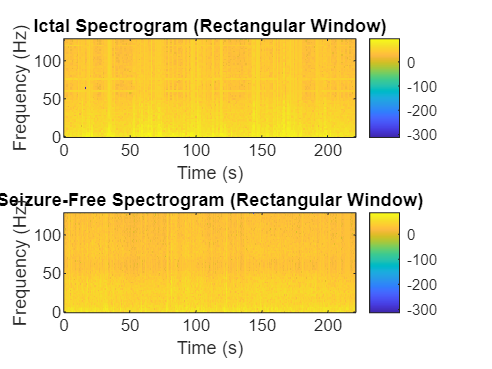

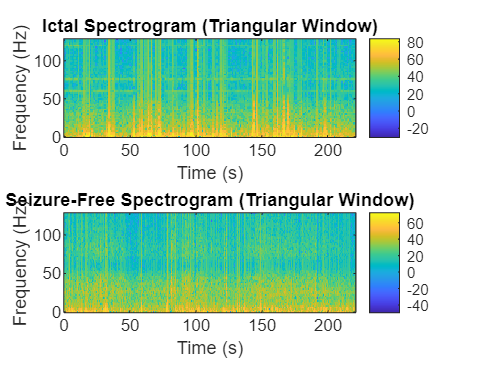

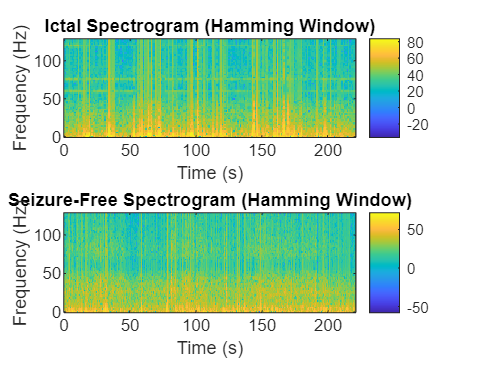

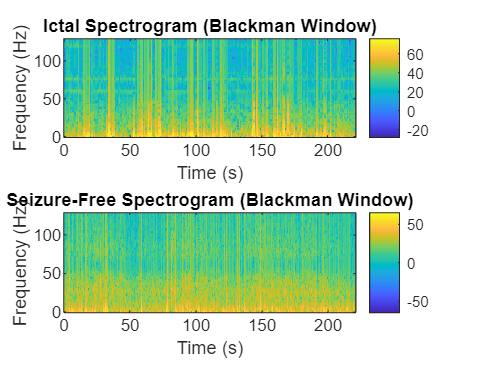

% Load the preprocessed averaged data
ictal_averaged_data = load('ictal_averaged.mat').ictal_averaged;
seizure_free_averaged_data = load('seizure_free_averaged.mat').seizure_free_averaged;

% Define parameters
Fs = 256; % Sampling rate in Hz
n_seconds = 2; % Window size in seconds
window_size = n_seconds * Fs; % Convert to samples
overlap = round(0.5 * window_size); % 50% overlap
n_freqs = 128; % FFT size

% Define window types
windows = {
    'Rectangular', ones(window_size, 1);
    'Triangular', triang(window_size);
    'Hamming', hamming(window_size);
    'Blackman', blackman(window_size)
};

% Loop over each window type
for w = 1:size(windows, 1)
    window_name = windows{w, 1}; % Window name
    window = windows{w, 2}; % Window function
    
    % Compute spectrograms
    ictal_spectrogram = compute_spectrogram(ictal_averaged_data, window, overlap, n_freqs, window_size, Fs);
    seizure_free_spectrogram = compute_spectrogram(seizure_free_averaged_data, window, overlap, n_freqs, window_size, Fs);

    % Time and frequency axes
    time_axis = (0:(size(ictal_spectrogram, 2) - 1)) * (window_size - overlap) / Fs;
    freq_axis = (0:(n_freqs / 2)) * Fs / n_freqs;

    % Plot spectrograms
    figure('Name', sprintf('%s Window', window_name));
    subplot(2, 1, 1);
    imagesc(time_axis, freq_axis, ictal_spectrogram);
    axis xy;
    xlabel('Time (s)');
    ylabel('Frequency (Hz)');
    title(sprintf('Ictal Spectrogram (%s Window)', window_name));
    colorbar;

    subplot(2, 1, 2);
    imagesc(time_axis, freq_axis, seizure_free_spectrogram);
    axis xy;
    xlabel('Time (s)');
    ylabel('Frequency (Hz)');
    title(sprintf('Seizure-Free Spectrogram (%s Window)', window_name));
    colorbar;
end

#### Output

**Objective**

The spectrograms were generated using different windowing techniques to analyze the effect of various windows (Rectangular, Triangular, Hamming, and Blackman) on the time-frequency representation of the ictal (seizure) and seizure-free EEG data.

**1. Rectangular Window**

**Ictal Spectrogram (Top)**:

- The rectangular window applies no smoothing, leading to sharp transitions between window segments.

- This results in spectral leakage, where the frequency content is smeared across adjacent frequencies.

- Seizure-related high-intensity frequencies (bright yellow) are visible but lack clarity.

**Seizure-Free Spectrogram (Bottom)**:

- The frequency content appears consistent but suffers from leakage, resulting in less distinct features.

**2. Triangular Window**

**Ictal Spectrogram (Top)**:

- The triangular window applies a linear tapering to the edges, reducing spectral leakage compared to the rectangular window.

- Seizure-related high-intensity frequencies are more distinct and better localized in the frequency domain.

**Seizure-Free Spectrogram (Bottom)**:

- Frequency content is represented with moderate smoothness and reduced leakage, making the spectrogram more interpretable.

**3. Hamming Window**

**Ictal Spectrogram (Top)**:

- The Hamming window provides a smoother transition by applying a weighted cosine taper, effectively reducing spectral leakage.

- Seizure-related bursts (vertical yellow bands) are well-defined, with enhanced clarity compared to the triangular window.

**Seizure-Free Spectrogram (Bottom)**:

- Normal brain activity is visualized with sharper frequency content and smooth transitions, making it ideal for general analysis.

**4. Blackman Window**

**Ictal Spectrogram (Top)**:

- The Blackman window provides the smoothest transition by applying a combination of cosine tapers, minimizing leakage further.

- Seizure-related high-intensity frequencies are highly localized and clear, making this window the best for frequency resolution.

**Seizure-Free Spectrogram (Bottom)**:

- The frequency content is sharp and well-separated, with minimal artifacts or leakage.

**Conclusion**

**Rectangular Window:**

- Best for computational efficiency but introduces significant spectral leakage, making it less ideal for precise frequency analysis.

**Triangular Window**: 

- A slight improvement over the rectangular window, with reduced leakage and better frequency representation.

**Hamming Window**: 

- Balances spectral leakage and frequency resolution, making it a widely used option in signal processing.

**Blackman Window**: 

- Provides the highest frequency resolution and the least spectral leakage, ideal for detailed frequency analysis at the cost of slightly higher computational overhead.

### Conclusion

#### **Summary**

- Preprocessed EEG data to isolate seizure and non-seizure states.

- Averaged multi-channel signals based on user selection.

- Generated spectrograms using STFT to visualize time-frequency behavior.

- Investigated the effects of overlapping, window sizes, and window types.

#### **Insights**

- High overlapping ratios smooth the spectrogram but increase computational costs.

- Larger windows improve frequency resolution but reduce time resolution.

- Window types significantly affect the spectrogram clarity, with Blackman offering the best leakage control.

#### **Future Improvements**

- Apply machine learning to classify ictal and seizure-free states based on spectrogram features.

- Test more advanced window functions and overlapping strategies.